% Original signal
f_signal = 3;                  
t = 0:0.001:1;                 
x = cos(2*pi*f_signal*t);      

% Configurations
fs_values = [5, 16];
sinc_widths = [3, 30]; 
noise_std = 0.1;

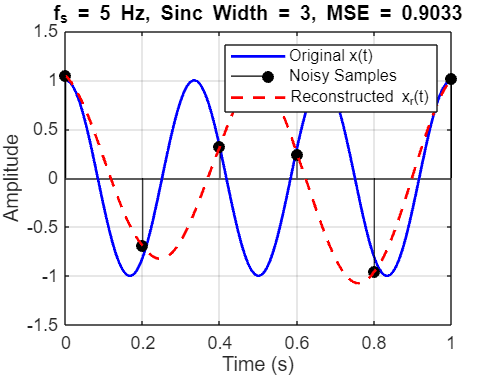

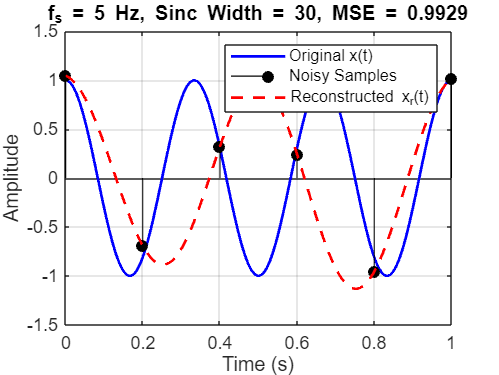

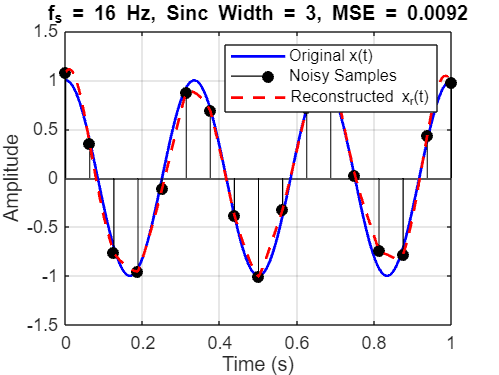

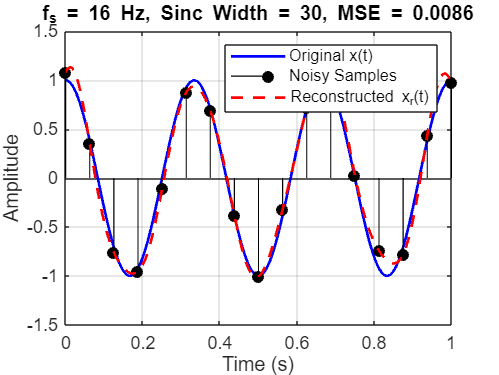

% For MSE tracking
mse_results = [];
case_labels = {};

% Loop over test cases
for i = 1:length(fs_values)
    fs = fs_values(i);
    T = 1/fs;
    n = 0:T:1;
    x_sample_clean = cos(2*pi*f_signal*n);
    x_sample_noisy = x_sample_clean + noise_std * randn(size(n));

    for j = 1:length(sinc_widths)
        sinc_w = sinc_widths(j);

        % Reconstruction
        x_rec = reconstruct(t, x_sample_noisy, fs, sinc_w);

        % MSE
        mse = mean((x - x_rec).^2);
        mse_results(end+1,:) = [fs, sinc_w, mse];
        case_labels{end+1} = sprintf('fs=%dHz, w=%d', fs, sinc_w);

        % Plot result
        figure;
        plot(t, x, 'b', 'LineWidth', 1.5); hold on;
        stem(n, x_sample_noisy, 'ko', 'filled', 'MarkerSize', 6, 'LineWidth', 0.6);
        plot(t, x_rec, 'r--', 'LineWidth', 1.5);
        xlabel('Time (s)'); ylabel('Amplitude');
        title(sprintf('f_s = %d Hz, Sinc Width = %d, MSE = %.4f', fs, sinc_w, mse));
        legend('Original x(t)', 'Noisy Samples', 'Reconstructed x_r(t)');
        grid on;
    end
end

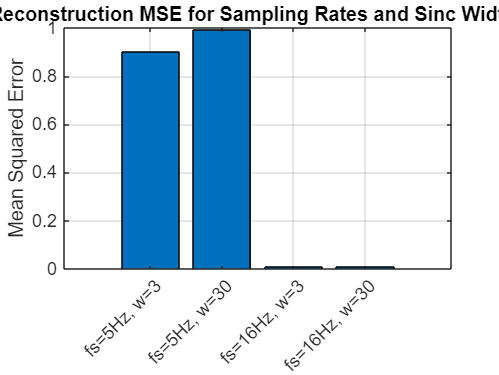

% MSE comparison bar plot
figure;
bar(mse_results(:,3));
xticklabels(case_labels);
xtickangle(45);
ylabel('Mean Squared Error');
title('Reconstruction MSE for Sampling Rates and Sinc Widths');
grid on;